# **Contact Time Calculation From Maximum Elevation Angle**

**Hongseok Kim, Researcher at HANCOM inSpace**

## I. Orbital Kinematics of SSO satellite

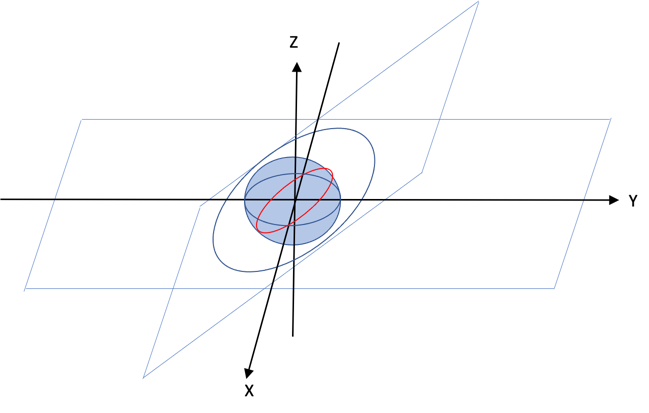

Suppose the ECI frame is on XYZ cartesian coordinate. The satellite orbit trajectory is stable in this frame.

- We alreay have satellite height(600km) and earth radious information, so all we have to choose is inclination angle $i$.

- In this coordinate, suppose the radious of orbital circle is 1 for simple calculation.

- Also, given the satellite hight, we can calculate the satellite's velocity and orbital period.

            
$$\begin{array}{l}
\textrm{flight}\;\textrm{velocity}:v=\sqrt[]{\frac{398600\ldotp 5}{6378\ldotp 14+h}}\left(\textrm{km}/s\right)\;\;\;\;\;\;,\textrm{orbital}\;\textrm{period}:\;P=2\pi \frac{\;6378\ldotp 14+h}{v}\left(\sec \right)\\
\textrm{if}\;h=600\;\textrm{km}\to \;v=7\ldotp 5579\textrm{km}/s\;,P=5801\ldotp 23\;\textrm{Sec}\;=\;1:36:41\ldotp 23\;\left(\textrm{hh}:\textrm{mm}:\textrm{ss}\right)\;\;
\end{array}$$


Therefore, we can express the orbital trajectory as follows.

            
$$\begin{array}{l}
\textrm{Satellite}\;\textrm{trajectory}\;\left(x,y,z\right)\;\textrm{at}\;\textrm{ECI}\;\textrm{frame}\\
\left(x,y,z\right)=\left(\cos \;\theta ,\cos \;i\;\sin \;\theta ,\sin \;i,\sin \;\theta \right),\;\;\theta =\frac{2\pi t}{P},i=\textrm{inclination}\;\textrm{angle}\;\left(-\frac{\pi }{2}\le i\le \frac{\pi }{2}\right)\\
\left(x,y,z\right)=\left(\cos \;\frac{2\pi t}{P},\cos \;i\;\sin \;\frac{2\pi t}{P},\sin \;i\;\sin \;\frac{2\pi t}{P}\right)
\end{array}$$


For changing from ECI frame to ECF frame, we should consider the rotation of earth.

- Suppose the direction of satellit rotation and earth rotation is same , +Z rotation (counterclockwise)

- The earth rotation period is known: $P_E =23:56:4\ldotp 09\;\left(\textrm{hh}:\textrm{mm}:\textrm{ss}\right)$

            
$$\begin{array}{l}
\textrm{Satellite}\;\textrm{trajectory}\;\left(x,y,z\right)\;\textrm{at}\;\textrm{ECF}\;\textrm{frame}\\
\;z\;\textrm{remains}\;\textrm{same},\;z=\sin \;i\;\sin \;\frac{2\pi t}{P}\\
\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\cos \frac{2\pi t\;}{P_E } & \sin \frac{2\pi t\;}{P_E }\\
-\sin \frac{2\pi t\;}{P_E } & \cos \frac{2\pi t\;}{P_E }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\cos \;\frac{2\pi t}{P}\\
\cos \;i\;\sin \;\frac{2\pi t}{P}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\cos \frac{2\pi t\;}{P_E }\cos \;\frac{2\pi t}{P}\;+\sin \frac{2\pi t\;}{P_E }\;\cos \;i\;\sin \;\frac{2\pi t}{P}\\
-\sin \frac{2\pi t\;}{P_E }\cos \;\frac{2\pi t}{P}+\cos \frac{2\pi t\;}{P_E }\;\cos \;i\;\sin \;\frac{2\pi t}{P}
\end{array}\right\rbrack \\
\textrm{Therefore},\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\cos \frac{2\pi t\;}{P_E }\cos \;\frac{2\pi t}{P}\;+\cos \;i\;\sin \frac{2\pi t\;}{P_E }\sin \;\frac{2\pi t}{P}\\
-\sin \frac{2\pi t\;}{P_E }\cos \;\frac{2\pi t}{P}+\cos \;i\;\cos \frac{2\pi t\;}{P_E }\;\sin \;\frac{2\pi t}{P}\\
\sin \;i\;\sin \;\frac{2\pi t}{P}
\end{array}\right\rbrack 
\end{array}$$


We can get the graph of basic trajectories.

i = 97.8/180*pi();
t_end = 2000;
h = 600;

v = sqrt(398600.5/(6378.14 + h));
P = 2 * pi() * (6378.14+h) / v;


r_E = 6378.14;
t = 0:1:t_end;
P_E = 23 * 3600 + 56 * 60 + 4.09;



x_ECI_x = cos(2*pi()*t/P);
x_ECI_y = cos(i)* sin(2*pi()*t/P);
x_ECI_z = sin(i)* sin(2*pi()*t/P);


x_ECF_x = cos(2*pi().*t/P_E).*cos(2*pi()*t/P) + cos(i).* sin(2*pi()*t/P_E) .* sin(2*pi()*t/P);
x_ECF_y = -sin(2*pi().*t/P_E).*cos(2*pi()*t/P) + cos(i).* cos(2*pi()*t/P_E) .* sin (2*pi()*t/P);
x_ECF_z = sin(i) * sin(2*pi()*t/P);


%plot3(x_ECI_x, x_ECI_y, x_ECI_z);
%plot3(x_ECF_x,x_ECF_y,x_ECF_z);
%plot(x_ECF_x,x_ECF_z);

### II. Calculating Elevation angle

We can express the position relationship by ground station and satellite by following diagram.

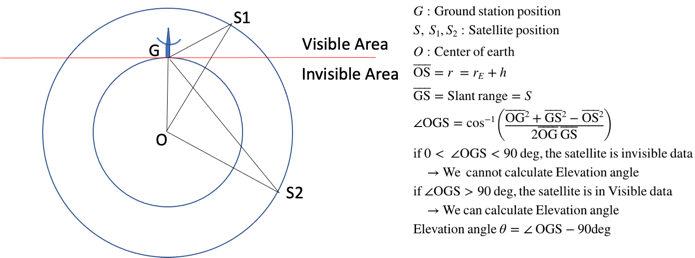

From Slant Range to Elevation Angle

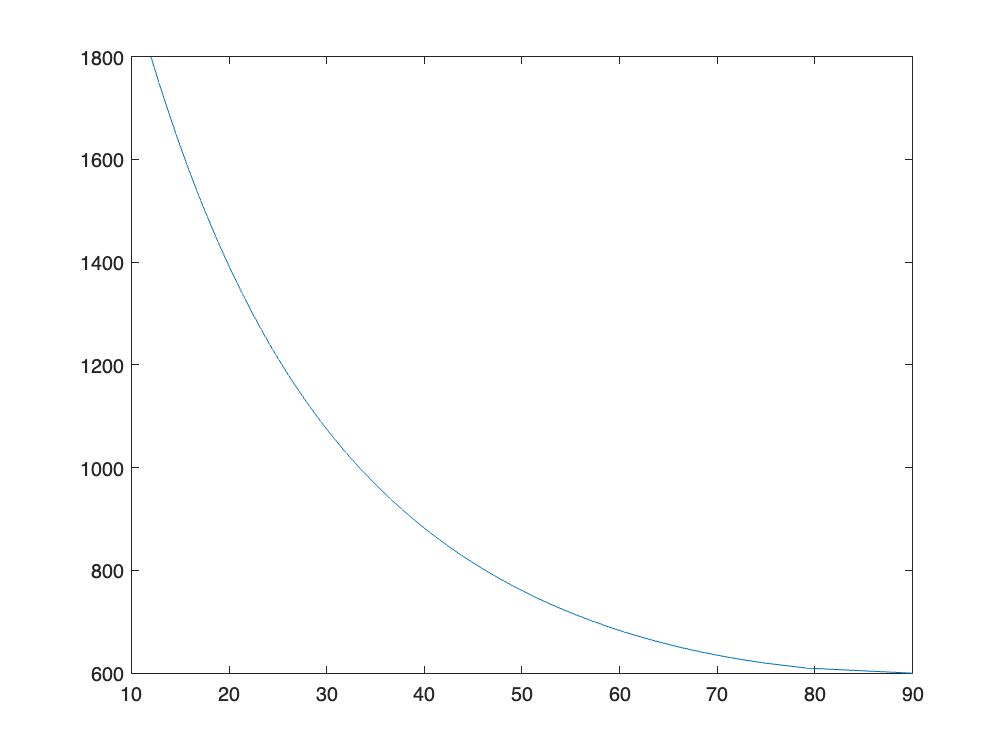

s = 600:10:1800;
og = 6378.14;
os = 6378.14 + 600;
elev_plus_90 = acos((og^2 + s.^2 - os.^2)./(2.*og.*s));
elev_angle = elev_plus_90*180/pi() - 90;
%plot(s,elev_angle)
plot(elev_angle,s)

## III. Calculating Contact Time From Maximum Elevation angle

In our SSO orbit satellite case,


$$\begin{array}{l}
\bar{\textrm{OG}} =r_E =6378\ldotp 14\textrm{km}\\
\bar{\textrm{OS}} =r_E +h=6978\ldotp 14\textrm{km}\\
\textrm{We}\;\textrm{should}\;\textrm{find}\;\bar{\textrm{GS}\;} \textrm{by}\;\textrm{calculating}\;\textrm{distance}\;\textrm{in}\;\textrm{ECF}\;\textrm{frame}
\end{array}$$


In the ECF frame, let G is at latitude = $\phi =36\degree \;21\prime 03″N$, which is the position of Daejeon, Korea, longitude = $\theta$, and assume G is on XZ plane.

Then we can get the position data of G, $G\left(x,y,z\right)=\left(r\;\cos \;\phi \;\cos \;\theta ,r\;\cos \;\phi \;\sin \;\theta ,r\;\sin \;\phi \right)$

From, $S\left(x,y,z\right)$at ECF frame we have got, we can calculate the length of $\bar{\textrm{GS}}$

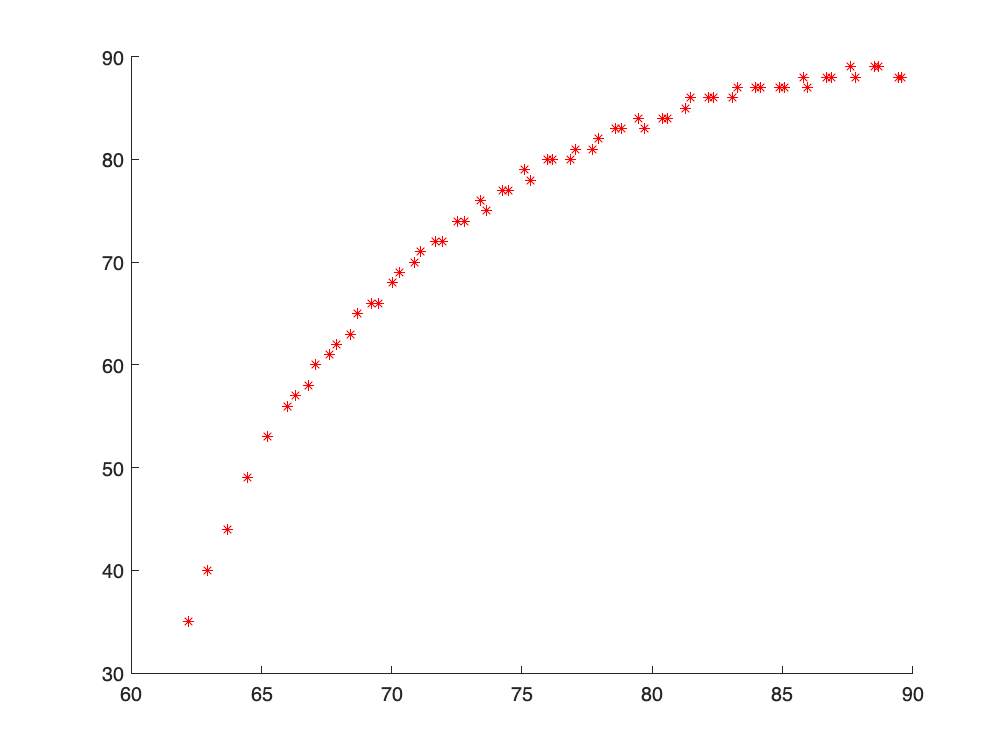


n = (-11 - (-5))/0.1+1;
data = zeros(n,2);
k = 1;

for theta_input = -11:0.1:-5

%theta = -8.3/180*pi();

theta = theta_input/180*pi();
phi = (36 + 21/60 + 3/3600)/180*pi();

G_x = r_E * cos(phi) * cos(theta);
G_y = r_E * cos(phi) * sin(theta);
G_z = r_E * sin(phi);


GS = sqrt(((r_E+h) * x_ECF_x - G_x).^2+((r_E+h) * x_ECF_y - G_y).^2+((r_E+h) * x_ECF_z - G_z).^2);
OGS_rad = acos((r_E^2+ GS.^2 -(r_E+h)^2)./(2.*r_E.*GS));
OGS_deg = OGS_rad/pi()*180;
elev = OGS_deg - 90;
%plot(t, elev)
observe_boundary = find(elev > 60);
T_min = min(observe_boundary);
T_max = max(observe_boundary);


elev_max = max(elev);
duration = T_max-T_min;
data(k,1) = elev_max;
data(k,2) = duration;
k = k+1;


end

scatter(data(:,1),data(:,2),'red','*')

## IV. Coverage Area Analysis